# Experiment No 4-

# Bit error rate of Quadrature Phase Shift Keying (QPSK) (with and without Gray labelling) in Additive White Gaussian Noise (AWGN)

#### Kushagra Khatwani

190020021

- Matlab Initialization-

close all;
clear;
clc;

- Message Signal-

%msg signal
num = 20000;                            %No of bits in the message
%Constellation
const = [+1+1i +3+1i +1+3i +3+3i ...
       -1+1i -3+1i -1+3i -3+3i ...
       -1-1i -3-1i -1-3i -3-3i ...
       +1-1i +3-1i +1-3i +3-3i];
% avg energy of constellation
avgE=mean(abs(const).^2);
msg = randi([0,1],num,1);               %Message

- (A) 16QAM Modulation (with gray labelling)-

% modulating message signal array
% 0000 -> -3-3i; 0001 -> -3-1i
% 0010 -> -3+3i; 0011 -> -3+1i
% 0100 -> -1-3i; 0101 -> -1-1i
% 0110 -> -1+3i; 0111 -> -1+1i
% 1000 -> 3-3i; 1001 -> 3-1i
% 1010 -> 3+3i; 1011 -> 3+1i
% 1100 -> +1-3i; 1101 -> +1-1i
% 1110 -> +1+3i; 1111 -> +1+1i

msg_reshape=reshape(msg,4,[])';
% temporary variable used for mapping
tmp=1000*msg_reshape(:,1)+100*msg_reshape(:,2)+10*msg_reshape(:,3)+msg_reshape(:,4);
% modulated signal array
mod=(tmp==1111)*(1+1i)+(tmp==1011)*(3+1i)+(tmp==1110)*(1+3i)+(tmp==1010)*(3+3i)+...
    (tmp==111)*(-1+1i)+(tmp==11)*(-3+1i)+(tmp==110)*(-1+3i)+(tmp==10)*(-3+3i)+...
    (tmp==101)*(-1-1i)+(tmp==1)*(-3-1i)+(tmp==100)*(-1-3i)+(tmp==0)*(-3-3i)+...
    (tmp==1101)*(1-1i)+(tmp==1001)*(3-1i)+(tmp==1100)*(1-3i)+(tmp==1000)*(3-3i);
mod=mod/sqrt(avgE); % normalizing to get avg energy as 1

- Demodualtion and Bit Error Rate Calculation-

ebnodb = -10:10;    % SNR array varying in the range of -10 to +10 dB in steps of 1 dB
number_snrs = length(ebnodb);
perr_est = zeros(number_snrs,1);   % Declaring array having all zeroes

%Demodulation
for k=1:number_snrs
    % calculating sigma from noise power
sigma=sqrt(1/(8*(10^(ebnodb(k)/10))));
% adding AWGN to modulated signal
w =  sigma*randn(num/4,1)+1i*sigma*randn(num/4,1);
% renormalizing the received array with avg signal energy
received=(mod+w)*sqrt(avgE);

% creating array of  size (num/4,16) with 
% each row as constellation array
arr1=ones(num/4,16).*const;
% creating array size (num/4,16) with 
% each column as received signal array
arr2=ones(num/4,16).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3,... 16) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx=12 -> 0000; idx=10 -> 0001
% idx=8 -> 0010; idx=6 -> 0011
% idx=11 -> 0100; idx=9 -> 0101
% idx=7 -> 0110; idx=5 -> 0111
% idx=16 -> 1000; idx=14 -> 1001
% idx=4 ->  1010; idx=2 -> 1011
% idx=15 -> 1100; idx=13 -> 1101
% idx=3 -> 1110; idx=1 -> 1111
demod=zeros(num,1);
for i=1:length(idx)
    if idx(i)==1
        demod(4*i-3:4*i)=[1 1 1 1];
    elseif idx(i)==2
        demod(4*i-3:4*i)=[1 0 1 1];
    elseif idx(i)==3
        demod(4*i-3:4*i)=[1 1 1 0];
    elseif idx(i)==4
        demod(4*i-3:4*i)=[1 0 1 0];
    elseif idx(i)==5
        demod(4*i-3:4*i)=[0 1 1 1];
    elseif idx(i)==6
        demod(4*i-3:4*i)=[0 0 1 1];
    elseif idx(i)==7
        demod(4*i-3:4*i)=[0 1 1 0];
    elseif idx(i)==8
        demod(4*i-3:4*i)=[0 0 1 0];
    elseif idx(i)==9
        demod(4*i-3:4*i)=[0 1 0 1];
    elseif idx(i)==10
        demod(4*i-3:4*i)=[0 0 0 1];
    elseif idx(i)==11
        demod(4*i-3:4*i)=[0 1 0 0];
    elseif idx(i)==12
        demod(4*i-3:4*i)=[0 0 0 0];
    elseif idx(i)==13
        demod(4*i-3:4*i)=[1 1 0 1];
    elseif idx(i)==14
        demod(4*i-3:4*i)=[1 0 0 1];
    elseif idx(i)==15
        demod(4*i-3:4*i)=[1 1 0 0];
    elseif idx(i)==16
        demod(4*i-3:4*i)=[1 0 0 0];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
perr_est(k)=sum(demod~=msg)/num;
end

- Plotting-

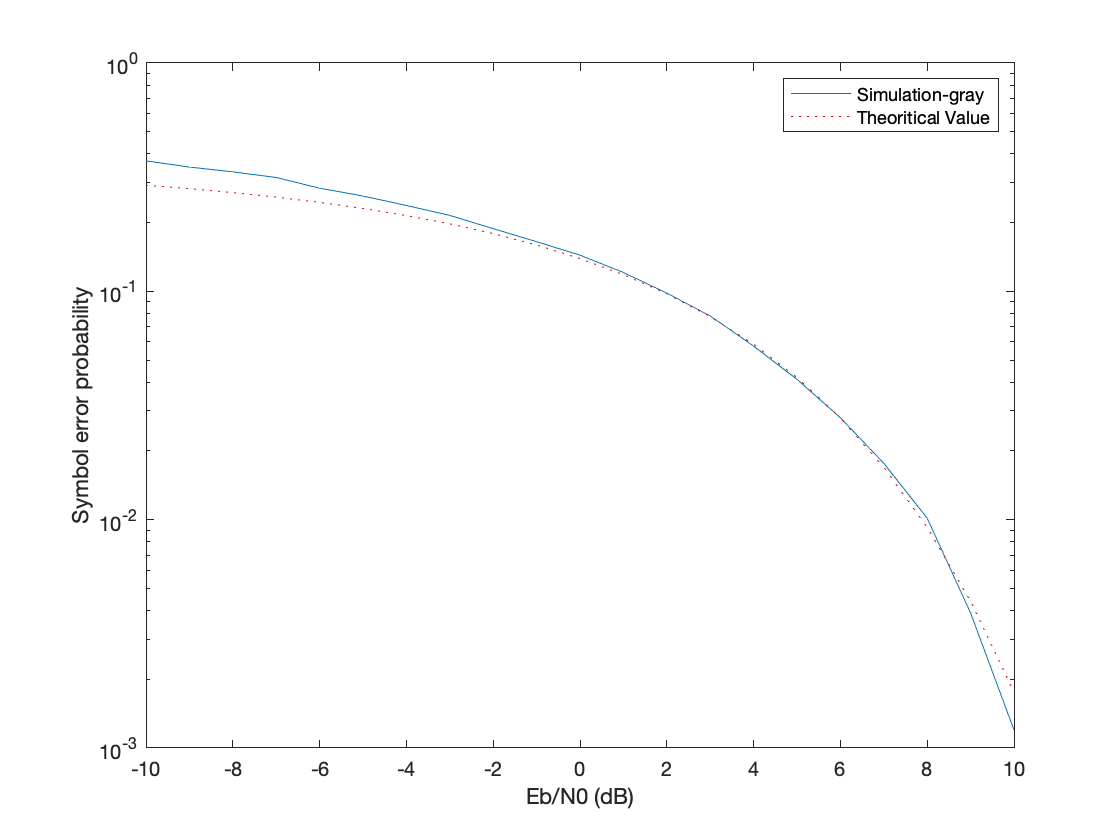

semilogy(ebnodb,perr_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(ebnodb/10); % raw SNR values
perr_th = (3/4)*qfunc(sqrt(4/5*snro)); % theoretical error (with gray coding)
semilogy(ebnodb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation-gray','Theoritical Value','Location','NorthEast');
hold off;

- (B)16QAM Modulation (without gray labelling)-

% modulating message signal array
% 0000 -> +1+1i; 0001 -> +3+1i
% 0010 -> +1+3i; 0011 -> +3+3i
% 0100 -> -1+1i; 0101 -> -3+1i
% 0110 -> -1+3i; 0111 -> -3+3i
% 1000 -> -1-1i; 1001 -> -3-1i
% 1010 -> -1-3i; 1011 -> -3-3i
% 1100 -> +1-1i; 1101 -> +3-1i
% 1110 -> +1-3i; 1111 -> +3-3i

msg_reshape=reshape(msg,4,[])';
% temporary variable used for mapping
tmp=1000*msg_reshape(:,1)+100*msg_reshape(:,2)+10*msg_reshape(:,3)+msg_reshape(:,4);
% modulated signal array
mod=(tmp==0)*(1+1i)+ (tmp==1)*(3+1i)+(tmp==10)*(1+3i)+(tmp==11)*(3+3i)+...
    (tmp==100)*(-1+1i)+(tmp==101)*(-3+1i)+(tmp==110)*(-1+3i)+(tmp==111)*(-3+3i)+...
    (tmp==1000)*(-1-1i)+(tmp==1001)*(-3-1i)+(tmp==1010)*(-1-3i)+(tmp==1011)*(-3-3i)+...
    (tmp==1100)*(1-1i)+(tmp==1101)*(3-1i)+(tmp==1110)*(1-3i)+(tmp==1111)*(3-3i);
mod=mod/sqrt(avgE); % normalizing to get avg energy as 1

- Demodualtion and Bit Error Rate Calculation-

ebnodb = -10:10;    % SNR array varying in the range of -10 to +10 dB in steps of 1 dB
number_snrs = length(ebnodb);
perr_est = zeros(number_snrs,1);   % Declaring array having all zeroes

%Demodulation
for k=1:number_snrs
    % calculating sigma from noise power
sigma=sqrt(1/(8*(10^(ebnodb(k)/10))));
% adding AWGN to modulated signal
w =  sigma*randn(num/4,1)+1i*sigma*randn(num/4,1);
% renormalizing the received array with avg signal energy
received=(mod+w)*sqrt(avgE);

% creating array of  size (num/4,16) with 
% each row as constellation array
arr1=ones(num/4,16).*const;
% creating array size (num/4,16) with 
% each column as received signal array
arr2=ones(num/4,16).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3,... 16) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx=1 -> 0000; idx=2 -> 0001
% idx=3 -> 0010; idx=4 -> 0011
% idx=5 -> 0100; idx=6 -> 0101
% idx=7 -> 0110; idx=8 -> 0111
% idx=9 -> 1000; idx=10 -> 1001
% idx=11 ->  1010; idx=12 -> 1011
% idx=13 -> 1100; idx=14 -> 1101
% idx=15 -> 1110; idx=16 -> 1111
demod=zeros(num,1);
for i=1:length(idx)
    if idx(i)==1
        demod(4*i-3:4*i)=[0 0 0 0];
    elseif idx(i)==2
        demod(4*i-3:4*i)=[0 0 0 1];
    elseif idx(i)==3
        demod(4*i-3:4*i)=[0 0 1 0];
    elseif idx(i)==4
        demod(4*i-3:4*i)=[0 0 1 1];
    elseif idx(i)==5
        demod(4*i-3:4*i)=[0 1 0 0];
    elseif idx(i)==6
        demod(4*i-3:4*i)=[0 1 0 1];
    elseif idx(i)==7
        demod(4*i-3:4*i)=[0 1 1 0];
    elseif idx(i)==8
        demod(4*i-3:4*i)=[0 1 1 1];
    elseif idx(i)==9
        demod(4*i-3:4*i)=[1 0 0 0];
    elseif idx(i)==10
        demod(4*i-3:4*i)=[1 0 0 1];
    elseif idx(i)==11
        demod(4*i-3:4*i)=[1 0 1 0];
    elseif idx(i)==12
        demod(4*i-3:4*i)=[1 0 1 1];
    elseif idx(i)==13
        demod(4*i-3:4*i)=[1 1 0 0];
    elseif idx(i)==14
        demod(4*i-3:4*i)=[1 1 0 1];
    elseif idx(i)==15
        demod(4*i-3:4*i)=[1 1 1 0];
    elseif idx(i)==16
        demod(4*i-3:4*i)=[1 1 1 1];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
perr_est(k)=sum(demod~=msg)/num;
end

- Plotting-

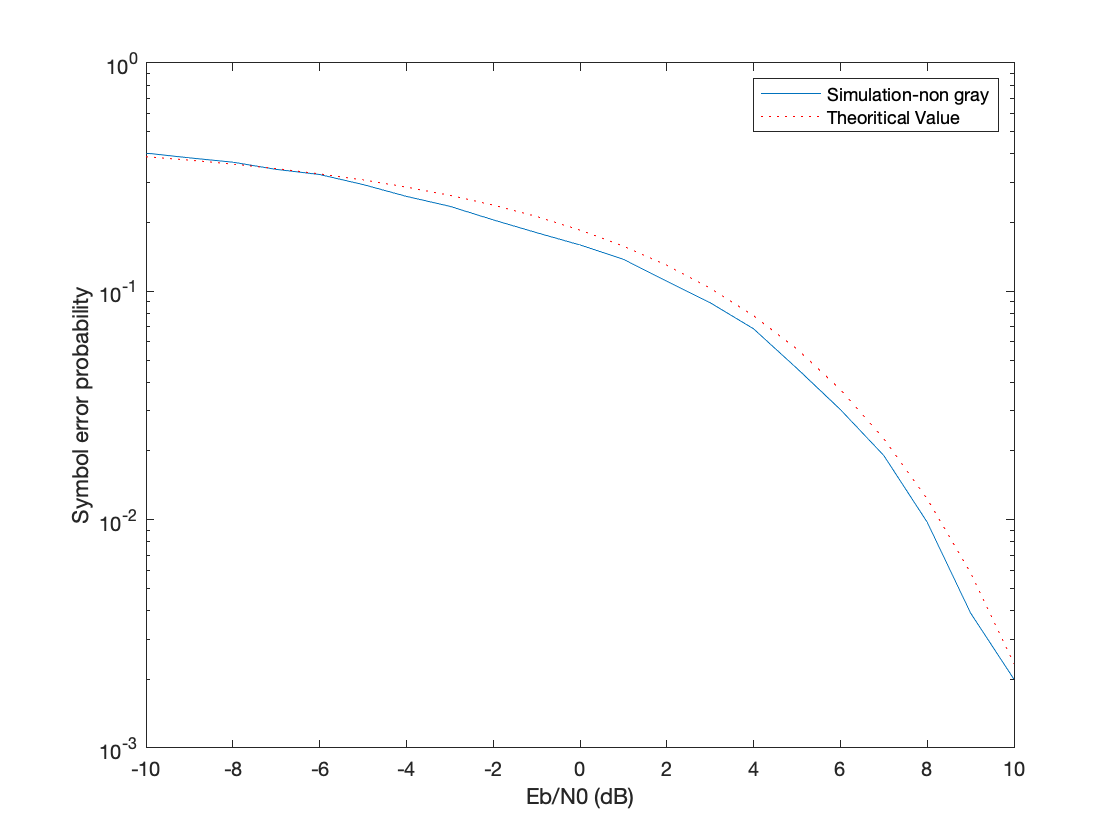

semilogy(ebnodb,perr_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(ebnodb/10); % raw SNR values
perr_th = qfunc(sqrt(4/5*snro)); % theoretical error (without gray coding)
semilogy(ebnodb,perr_th,':r'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation-non gray','Theoritical Value','Location','NorthEast');
hold off;